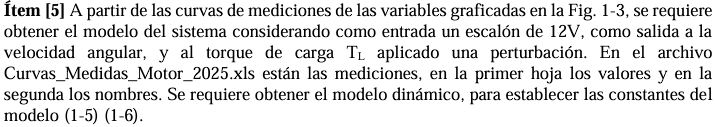

clear all; clc; close all;

opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Hoja1";
opts.DataRange = "A2:E1500";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\Maca\Documents\UNC\4toAÑO\1CUATRI\SC2\Folder Github TP´s\Control-System-II-TP-s\TP1\documentation\Curvas_Medidas_Motor_2025_v.xls", opts, "UseExcel", false);

VarName1 = tbl.VarName1;
VarName2 = tbl.VarName2;
VarName3 = tbl.VarName3;
VarName4 = tbl.VarName4;
VarName5 = tbl.VarName5;
clear opts tbl